# Load Spikes Data for the correlation matrix

## Load data from the results of the spike sorting, and information about the electrode

load('amplifier_res.mat', 'spikesByCluster'); % spikes are in sample, each
load('amplifier_res.mat', 'clusterSites'); % spieSite (JRC), where the waveform of the spikes is maximum. !!!The real one is the siteMap from prm file!!! -1
load('amplifier_res.mat', 'meanWfLocalRaw'); % (37.4./192); %uV/bit / gain -> convert to physical uV
[rawRecordings,sampleRate,bitScaling,shankMap, siteMap,siteLoc,probePad]=read_prb_file; % read paramater about the electrode, and row data file. 
load('curated_ripples.mat');
load('amplifier_res.mat', 'spikeTimes')
load('amplifier_res.mat', 'spikeClusters')

## Get the lenght of the data based on the siza of the row data file

filename='amplifier.dat';
FileInfo = dir(filename);
nChansInRawFile=128; 
num_samples = FileInfo.bytes/(nChansInRawFile * 2); % int16 = 2 bytes
%fid=fopen([filename(1:end-8),'.dat'],'r');
%RowData.Data = fread(fid, [nChansInRawFile, num_samples], 'int16');
%a=memmapfile(filename, 'Format','int16');
% RowData=reshape(a.Data, [nChansInRawFile, num_samples]);
% fclose(fid);
% RealTimeLength=size(RowData,2).;

sample_rate=20000;
bin=10; % [ms]
time=linspace(0,(num_samples./sample_rate),ceil((num_samples./sample_rate)/(bin/1000)));

## Constraction matrix during ripple, during theta

% Note: The LFP data originates from the original *.dat recordings from both the left and right hippocampus.
% Theta oscillations are particularly strong in the stratum radiatum, but they exhibit an opposite phase compared to
% those in the stratum pyramidale, which may lead to complications. I have chosen to focus on theta
% oscillations from the pyramidal layer, even though they are not as pronounced there.


%Selected time points for correlation matrix; %Note: intristing_segment 83.080sec 9 recording rEO_06
start_theta=53.241 %sec

start_theta = 53.2410

stop_theta=101.109 %sec

stop_theta = 101.1090


% Loading selected channels
selectedChannels = [93, 37]+1; % LEFT - RIGHT Channels from Str.Pir. Number from Neuroscope
% Map the binary file into memory
RowDat_map_memory_file = memmapfile(char(rawRecordings), 'Format', 'int16');
% Calculate the total number of samples per channel

% Note: The total number of data points divided by the number of channels gives the samples per channel
totalDataPoints = numel(RowDat_map_memory_file.Data);
samplesPerChannel = totalDataPoints / nChansInRawFile;

% Initialize a matrix to hold the data from the selected channels
LFPFromSelectedChannels = zeros( numel(selectedChannels),samplesPerChannel, 'int16');

% Extract data for each selected channel
for i = 1:numel(selectedChannels)
    channelIdx = selectedChannels(i);
    disp(channelIdx)
    LFPFromSelectedChannels(i, :) = RowDat_map_memory_file.Data(channelIdx:nChansInRawFile:end);
    
    % Update and display the loading progress
    progressPercentage = (i / numel(selectedChannels)) * 100;
    fprintf(['Loading channel#' num2str(channelIdx) ' %.2f%%\n'], progressPercentage);
    
end

    94


Loading channel#94 50.00%


    38


Loading channel#38 100.00%


fprintf('Data loading complete.\n');

Data loading complete.


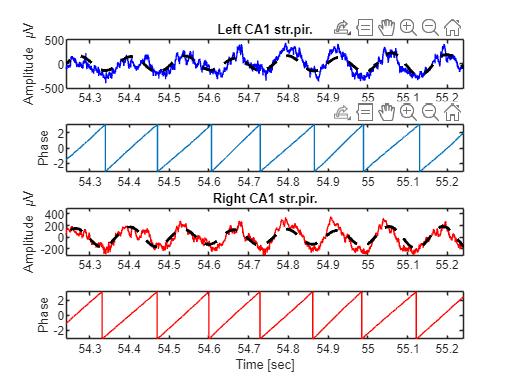


% At this point, LfpFromSelectedChannels contains the data from your selected channels
% with each row corresponding to one of the channels.

LFPFromSelectedChannels=double(LFPFromSelectedChannels).*bitScaling;  % The smallest voltage step the ADC can resolve – also called the least significant bit (LSB) – is (2.45 V) / (216) = 37.4 μV.  Dividing this LSB level by the RHD2000 amplifier gain of 192
Time_vector_LFP=linspace(0,num_samples./sampleRate,length(LFPFromSelectedChannels));

start_theta_sample=min(find(start_theta<Time_vector_LFP & Time_vector_LFP<stop_theta));
stop_theta_sample=max(find(start_theta<Time_vector_LFP & Time_vector_LFP<stop_theta));

% Filter the LFP signal to isolate the theta band (4-8 Hz)
lowCut = 4; % in Hz
highCut = 8; 

% Design a bandpass filter using 'designfilt'
bpFilt = designfilt('bandpassiir', ...
    'FilterOrder',40, ... % Adjust the order based on the desired filter sharpness and stability
    'HalfPowerFrequency1', lowCut, ...
    'HalfPowerFrequency2', highCut, ...
    'SampleRate', sampleRate, ...
    'DesignMethod', 'butter'); % Using a Butterworth filter for a flat response in the passband

% Display the filter
%fvtool(bpFilt); 

thetaLFP=filtfilt(bpFilt,(LFPFromSelectedChannels'));

% Calculate the instantaneous phase of theta oscillations using the Hilbert transform
thetaHilbert = hilbert(thetaLFP);
thetaPhase = angle(thetaHilbert);

%plotting 2nd selected sec
figure()
subplot(4,1,1)
plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),LFPFromSelectedChannels(1,start_theta_sample:stop_theta_sample),'b')
hold on; 
plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),thetaLFP(start_theta_sample:stop_theta_sample,1),'--k',"LineWidth",2)
xlim([start_theta+1, start_theta+2]);
ylabel('Amplitude \muV')
title('Left CA1 str.pir.')
subplot(4,1,2)
plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),thetaPhase(start_theta_sample:stop_theta_sample,1))
xlim([start_theta+1, start_theta+2]);
ylabel('Phase')
subplot(4,1,3)
plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),LFPFromSelectedChannels(2,start_theta_sample:stop_theta_sample),'r')
hold on; plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),thetaLFP(start_theta_sample:stop_theta_sample,2),'--k',"LineWidth",2)
ylabel('Amplitude \muV')
xlim([start_theta+1, start_theta+2]);
title('Right CA1 str.pir.')
subplot(4,1,4)
plot(Time_vector_LFP(start_theta_sample:stop_theta_sample),thetaPhase(start_theta_sample:stop_theta_sample,2),'r')
xlim([start_theta+1, start_theta+2]);
ylabel('Phase')
xlabel('Time [sec]')

rad2deg(linspace(-pi,pi,37))+180

for cellID=1:(numel(spikesByCluster))
    % Convert spike times from seconds to sample indices
    spikeIndices = double(spikeTimes(spikeClusters==cellID));

    % Extreact spikes by the start-stop of the theta
    spikeIndices_selected=spikeIndices(find(start_theta_sample< spikeIndices & spikeIndices< stop_theta_sample));

    if ~isempty(spikeIndices_selected)
        % Extract theta phase at each spike time
        spikePhases = thetaPhase(spikeIndices_selected);

        % Simple histogram of spike phases
        figure();
        subplot(2,1,1)
        polarhistogram(spikePhases, 36); % 36 bins for 0 to 2*pi
        subplot(2,1,2)
        original=histcounts(spikePhases,linspace(-pi,pi,37))


bar([linspace(0,720,72)],[original original])
       %  xticks((-pi:pi/3:pi))
        % xticklabels(rad2deg(-pi:pi/3:pi))
        % xlim([-pi pi]);
        title(['Spike Phase Distribution of Neurons#' num2str(cellID)]);

        % hold on  
        % plot(0:0.1:2*pi,sin(0:0.1:2*pi))
        %Note statistic is missing

    % saveas(gcf, fullfile(plotpath, ['cell_phase_' num2str(cellID) '.png']), 'png');


    end
end

%% Theta, SPW-Rs Activity Matix unifnished....

clear   Activitymatrix

Activitymatrix=zeros(length(cellID),length(time));
for Cell_ID=1:(numel(spikesByCluster))
      Activitymatrix(Cell_ID,:)=histc((spikeTimes(spikeClusters==Cell_ID))./sample_rate,time);
 %  Activitymatrix(Cell_ID,:)=histc(spikesByCluster{Cell_ID}(:,:)./sample_rate,time);
 %  Activitymatrix_times(Cell_ID,:)={spikeTimes(spikeClusters==(Assembly_cellID(Cell_ID)))};
end

zSpikeCount = zscore(Activitymatrix');
CorrMatrix = corr(zSpikeCount);
figure()
imagesc(CorrMatrix)
axis tight
axis square


% AssemblyTemplates=assembly_patterns(Activitymatrix);
% Activities=assembly_activity(AssemblyTemplates,Activitymatrix);
% unique_PutitativeStructure=unique(PutitativeStructure);
% color_for_stem=colormap("lines");
% close all

%

% .......unfinished
% t = 0:0.001:1; % 
% cleanSignal = sin(2*pi*10*t) + 0.5*sin(2*pi*20*t + pi/4); % Example signal; replace with your signal
% 
% % Step 1: Sinusoidal Fitting
% % Define the sinusoidal fit model
% sinusoidalModel = fittype('a*sin(b*x + c) + d', ...
%     'independent', 'x', ...
%     'coefficients', {'a', 'b', 'c', 'd'});
% 
% % Fit the model to the data
% [fitResult, gof] = fit(t', cleanSignal', sinusoidalModel);
% 
% % Extract parameters from the fit
% amplitude = fitResult.a;
% frequency = fitResult.b / (2*pi); % Convert from rad/s to Hz
% phase = fitResult.c;
% dcOffset = fitResult.d;
% 
% % Display fit parameters
% fprintf('Amplitude: %f\n', amplitude);
% fprintf('Frequency: %f Hz\n', frequency);
% fprintf('Phase: %f radians\n', phase);
% fprintf('DC Offset: %f\n', dcOffset);
% 
% % Step 2: Analytical Signal and Phase Extraction
% % Create analytical signal using Hilbert transform
% analyticalSignal = hilbert(cleanSignal);
% 
% % Calculate instantaneous phase from the analytical signal
% instantaneousPhase = angle(analyticalSignal);
% 
% % Plot the results
% figure;
% subplot(3,1,1);
% plot(t, cleanSignal);
% title('Cleaned Signal');
% xlabel('Time (s)');
% ylabel('Amplitude');
% 
% subplot(3,1,2);
% plot(t, real(analyticalSignal));
% hold on;
% plot(t, imag(analyticalSignal));
% title('Analytical Signal (Real and Imaginary Parts)');
% xlabel('Time (s)');
% legend('Real Part', 'Imaginary Part');
% 
% subplot(3,1,3);
% plot(t, instantaneousPhase);
% title('Instantaneous Phase');
% xlabel('Time (s)');
% ylabel('Phase (radians)');
